[1] Deb, Kalyanmoy, J. Sundar, Udaya Bhaskara Rao N, and Shamik Chaudhuri. *Reference Point Based Multi-Objective Optimization Using Evolutionary Algorithms*. International Journal of Computational Intelligence Research, Vol. 2, No. 3, 2006, pp. 273–286. Available at [https://www.softcomputing.net/ijcir/vol2-issu3-paper4.pdf](https://www.softcomputing.net/ijcir/vol2-issu3-paper4.pdf)

[2] Ray, T., and K. M. Liew. *A Swarm Metaphor for Multiobjective Design Optimization*. Engineering Optimization 34, 2002, pp.141–153.

## **Designing a welden beam——20200420**


%学习视频：https://www.bilibili.com/video/BV1AK4y1k7N3
Aineq = [1,0,0,-1];
bineq = 0;

%%4个决策变量的上下限
lb = [0.125,0.1,0.1,0.125];
ub = [5,10,10,5];

%%设置目标函数和非线性约束函数。
nlcon = @nonlcon;
fun = @objval;

**Multiobjective Problem Formulation and **`paretosearch`** Solution**

解决双目标优化问题，有以下几个方式：

1.设置最大挠度，并找到满足最大挠度约束的设计上的最小单目标制造成本。

2.设定一个最大的制造成本，并在满足制造成本约束的设计上找到一个单一目标的最小偏差。

3.解决一个多目标问题，可视化两个目标之间的权衡。

Solve the problem using `paretosearch` with the `'``psplotparetof``'` plot function. To reduce the amount of diagnostic display information, set the `Display` option to `'off'`.

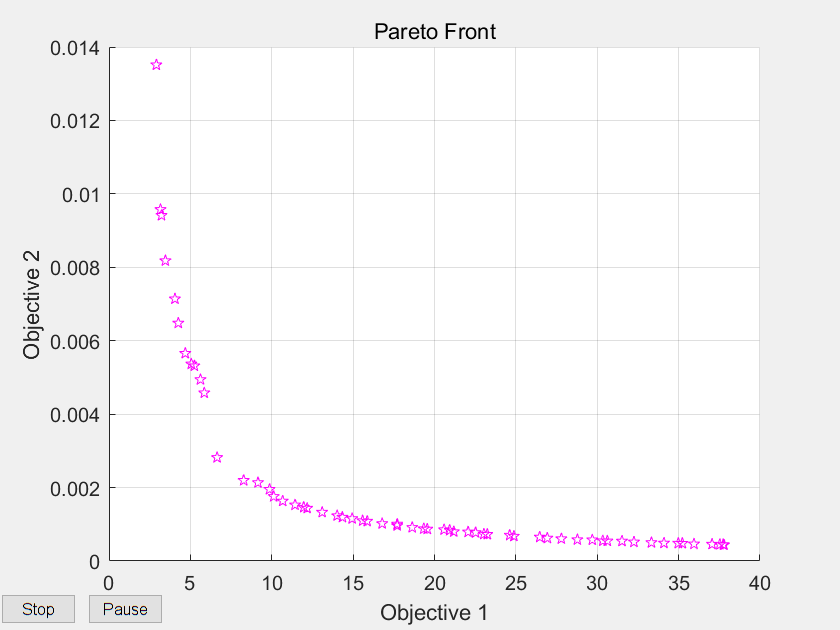

%
opts_ps = optimoptions('paretosearch','Display','off','PlotFcn','psplotparetof');
rng default % For reproducibility
[x_ps1,fval_ps1,~,psoutput1] = paretosearch(fun,4,Aineq,bineq,[],[],lb,ub,nlcon,opts_ps);

%
disp("Total Function Count: " + psoutput1.funccount);

Total Function Count: 1870


This solution looks like a smoother curve, but it has a smaller extent of Objective 2. The solver takes over three times as many function evaluations when using 160 Pareto points instead of 60.

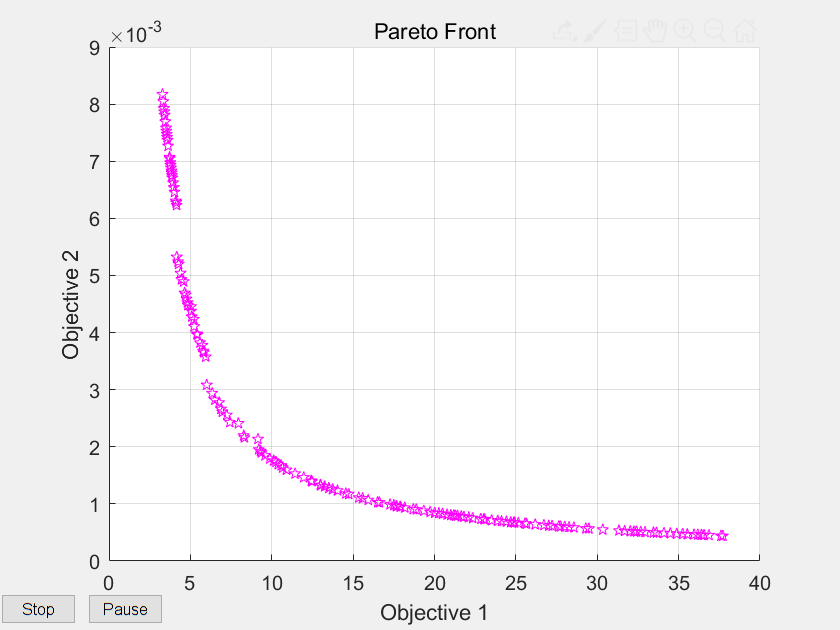

%For a smoother Pareto front, try using more points.
%对于光滑的前沿面，可以扩大种群规模60→160
npts = 160; % The default is 60
opts_ps.ParetoSetSize = npts;
[x_ps2,fval_ps2,~,psoutput2] = paretosearch(fun,4,Aineq,bineq,[],[],lb,ub,nlcon,opts_ps);

disp("Total Function Count: " + psoutput2.funccount);

Total Function Count: 6254


`gamultiobj`** Solution（多目标遗传算法）**

要看我们的算法效果有何区别，我们来尝试使用gamultiobj方法解决该问题。与前面的解决方案一样设置等效的选项。

但是！因为gamultiobj求解器在最优的Pareto前只保留了不到一半的个体解，所以这里使用的个体点是之前的两倍。（即种群大小X2）



opts_ga = optimoptions('gamultiobj','Display','off','PlotFcn','gaplotpareto','PopulationSize',2*npts);
[x_ga1,fval_ga1,~,gaoutput1] = gamultiobj(fun,4,Aineq,bineq,[],[],lb,ub,nlcon,opts_ga);

disp("Total Function Count: " + gaoutput1.funccount);

`gamultiobj` takes tens of thousands of function evaluations, whereas `paretosearch` takes only thousands.【这句话待理解】

**Compare Solutions（结果比较）**

`gamultiobj方法看起来和之前的paretosearch方法是有区别的，因为绘制的尺度不同，所以很难分辨两者的解决效果。所以下面将两者的解集绘制到同一坐标系下，并使用相同的尺度比例（scale）。`

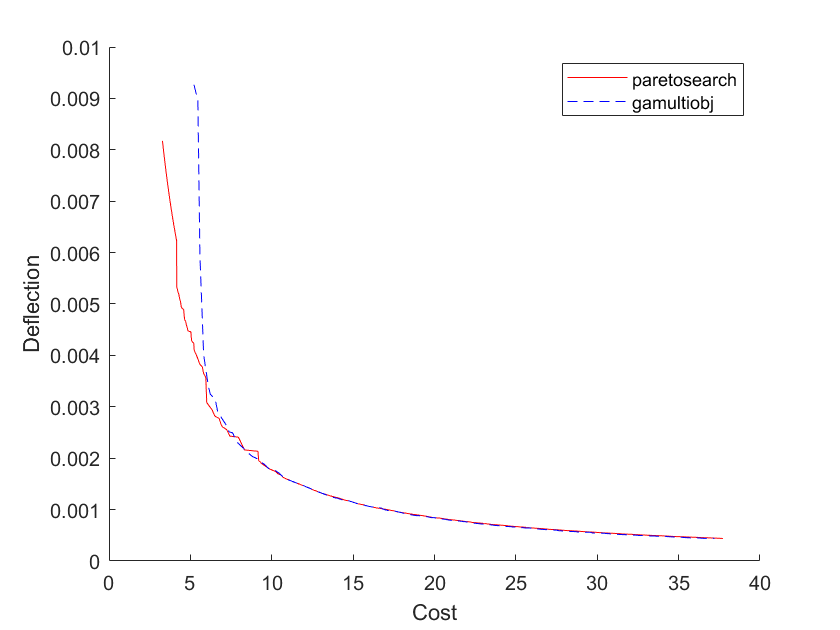


fps2 = sortrows(fval_ps2,1,'ascend');
figure
hold on
plot(fps2(:,1),fps2(:,2),'r-')
fga = sortrows(fval_ga1,1,'ascend');
plot(fga(:,1),fga(:,2),'b--')
xlim([0,40])
ylim([0,1e-2])
legend('paretosearch','gamultiobj')
xlabel 'Cost'
ylabel 'Deflection'
hold off

根据上面的绘图结果，我们可以看到，在图最右边的部分gamultiobj方案更好（其实效果差不多），而在图最左边的部分paretosearch方案更好。注：越靠近前沿面的点，越优。paretosearch使用更少的函数计算来获得其解决方案。

通常，当问题没有非线性约束时，paretosearch至少与gamultiobj一样精确。但是，结果的Pareto集可能有一些不同的范围。在这种情况下，非线性约束的存在会导致paretosearch解在部分范围内精度较低。

paretosearch的主要优点之一是，它通常需要更少的函数评估，也就是收敛速度快。

**Start from Single-Objective Solutions**

为了帮助求解者找到更好的解决方案，从解决方案的各个点开始，首先将单个目标函数最小化。pickindex函数从objval函数返回一个目标。使用fmincon查找单目标优化。然后使用这些解作为多目标搜索的初始点。

x0 = zeros(2,4);
x0f = (lb + ub)/2;
opts_fmc = optimoptions('fmincon','Display','off','MaxFunctionEvaluations',1e4);
x0(1,:) = fmincon(@(x)pickindex(x,1),x0f,Aineq,bineq,[],[],lb,ub,@nonlcon,opts_fmc);
x0(2,:) = fmincon(@(x)pickindex(x,2),x0f,Aineq,bineq,[],[],lb,ub,@nonlcon,opts_fmc);

objval(x0(1,:))

ans =     2.3810    0.0158



objval(x0(2,:))

ans =    76.7546    0.0004


最小的花费是2.381，它的挠度是0.158。最小挠度为0.0004，成本为76.7253。绘制的曲线在其范围的末端非常陡峭，这意味着如果你的花费比最小值稍高一点，你得到的挠度会小很多，或者如果你的花费比最小值稍高一点，你得到的挠度会小很多。

从单目标解决方案开始进行paretosearch方法。

opts_ps.InitialPoints = x0;
opts_ps.PlotFcn = [];
[x_psx0,fval_ps1x0,~,psoutput1x0] = paretosearch(fun,4,Aineq,bineq,[],[],lb,ub,nlcon,opts_ps);

disp("Total Function Count: " + psoutput1x0.funccount);

Total Function Count: 1326


Start `ga/gamultiobj` from the same initial points, and remove its plot function.开始进行gamultiobj方法

opts_ga.InitialPopulationMatrix = x0;
opts_ga.PlotFcn = [];
[~,fval_ga,~,gaoutput] = gamultiobj(fun,4,Aineq,bineq,[],[],lb,ub,nlcon,opts_ga);
disp("Total Function Count: " + gaoutput.funccount);

Total Function Count: 32641


Plot the solutions on the same axes.

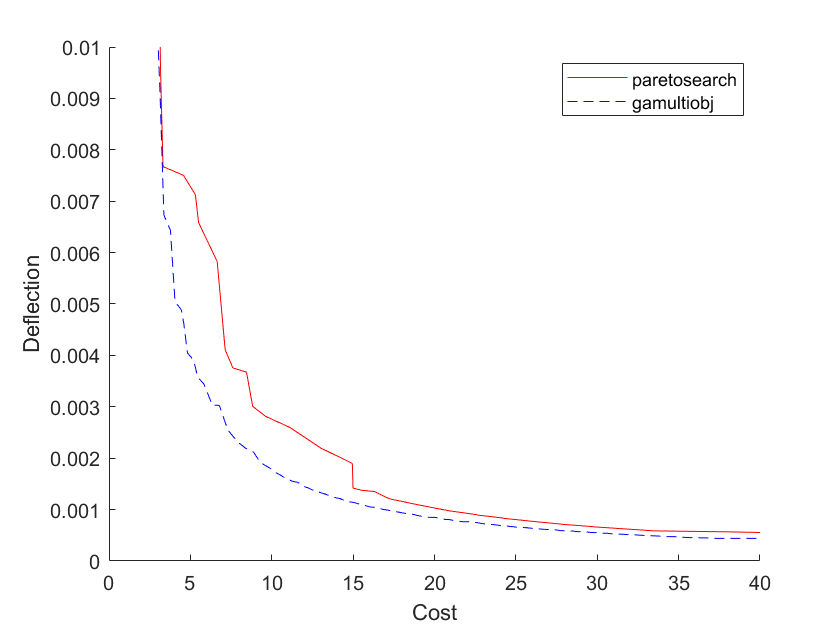

fps = sortrows(fval_ps1x0,1,'ascend');
figure
hold on
plot(fps(:,1),fps(:,2),'r-')
fga = sortrows(fval_ga,1,'ascend');
plot(fga(:,1),fga(:,2),'b--')
xlim([0,40])
ylim([0,1e-2])
legend('paretosearch','gamultiobj')
xlabel 'Cost'
ylabel 'Deflection'
hold off

通过从单目标解开始，gamultiobj解在整个标绘范围内略优于paretosearch解。然而，gamultiobj需要十倍的函数计算才能得到它的解。

**Hybrid Function**

`gamultiobj` can call the hybrid function `fgoalattain` automatically to attempt to reach a more accurate solution. See whether the hybrid function improves the solution.

gamultiobj可以调用混合函数`fgoalattain`自动尝试达到更精确的解决方案。查看混合函数是否改进了解决方案。

opts_ga.HybridFcn = 'fgoalattain';
[xgah,fval_gah,~,gaoutputh] = gamultiobj(fun,4,Aineq,bineq,[],[],lb,ub,nlcon,opts_ga);
disp("Total Function Count: " + gaoutputh.funccount);

Total Function Count: 45624


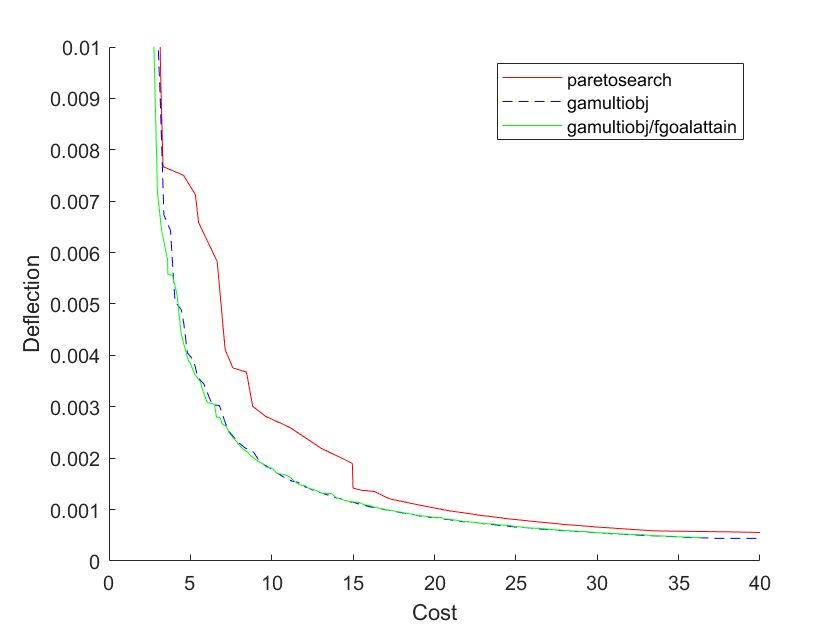

fgah = sortrows(fval_gah,1,'ascend');
figure
hold on
plot(fps(:,1),fps(:,2),'r-')
plot(fga(:,1),fga(:,2),'b--')
plot(fgah(:,1),fgah(:,2),'g-')
xlim([0,40])
ylim([0,1e-2])
legend('paretosearch','gamultiobj','gamultiobj/fgoalattain')
xlabel 'Cost'
ylabel 'Deflection'
hold off

混合函数对gamultiobj解决方案有轻微的改进，主要是在图的最左边。

**Run** `fgoalattain` **Manually from** `paretosearch` **Solution Points**

Although `paretosearch` has no built-in hybrid function, you can improve the `paretosearch` solution by running `fgoalattain` from the `paretosearch` solution points. Create a goal and weights for `fgoalattain` by using the same setup for `fgoalattain` as described in [gamultiobj Hybrid Function](https://ww2.mathworks.cn/help/gads/genetic-algorithm-options.html#bu7fltk-1).

虽然paretosearch没有内置的混合函数，但是您可以通过从paretosearch解决方案点运行`fgoalattain`来改进paretosearch解决方案。使用与gamultiobj混合函数中描述的相同的`fgoalattain`设置，为`fgoalattain`创建目标和权重。

Fmax = max(fval_ps1x0);
nobj = numel(Fmax);
Fmin = min(fval_ps1x0);
w = sum((Fmax - fval_ps1x0)./(1 + Fmax - Fmin),2);
p = w.*((Fmax - fval_ps1x0)./(1 + Fmax - Fmin));
xnew = zeros(size(x_psx0));
nsol = size(xnew,1);
fvalnew = zeros(nsol,nobj);
opts_fg = optimoptions('fgoalattain','Display','off');
nfv = 0;
for ii = 1:nsol
    [xnew(ii,:),fvalnew(ii,:),~,~,output] = fgoalattain(fun,x_psx0(ii,:),fval_ps1x0(ii,:),p(ii,:),...
        Aineq,bineq,[],[],lb,ub,nlcon,opts_fg);
    nfv = nfv + output.funcCount;
end
disp("fgoalattain Function Count: " + nfv)

fgoalattain Function Count: 5798


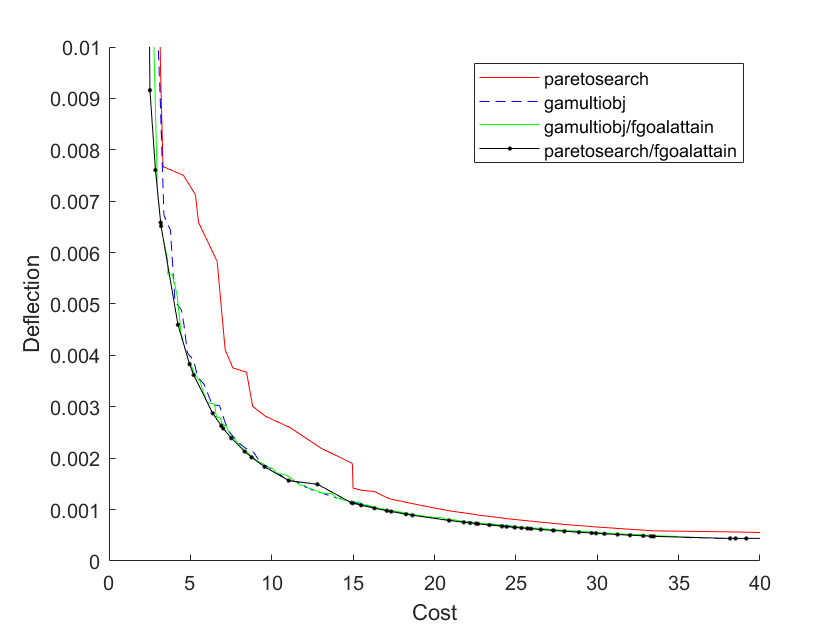

fnew = sortrows(fvalnew,1,'ascend');
figure
hold on
plot(fps(:,1),fps(:,2),'r-')
plot(fga(:,1),fga(:,2),'b--')
plot(fgah(:,1),fgah(:,2),'g-')
plot(fnew(:,1),fnew(:,2),'k.-')
xlim([0,40])
ylim([0,1e-2])
legend('paretosearch','gamultiobj','gamultiobj/fgoalattain','paretosearch/fgoalattain')
xlabel 'Cost'
ylabel 'Deflection'

The combination of `paretosearch` and `fgoalattain` creates the most accurate Pareto front. Zoom in to see.

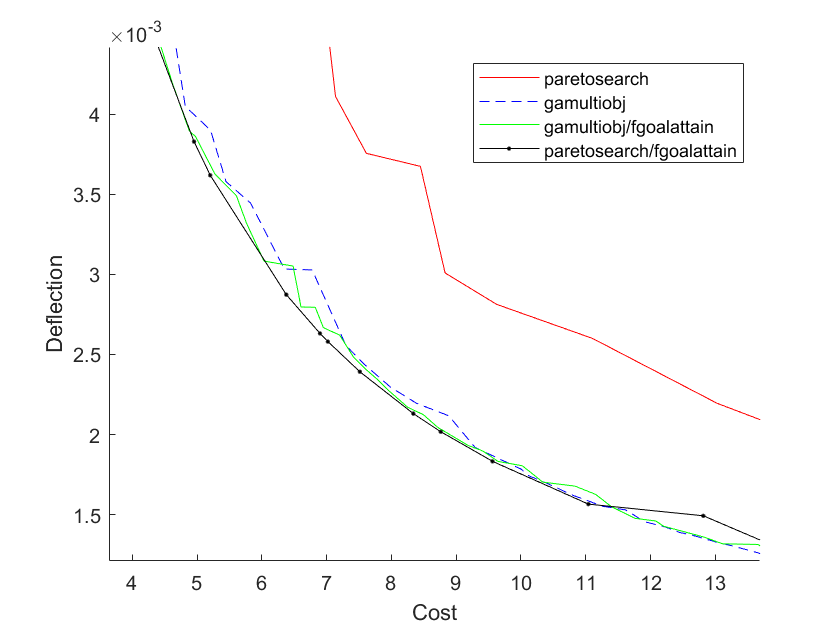

xlim([3.64 13.69])
ylim([0.00121 0.00442])
hold off

Even with the extra `fgoalattain` computations, the total function count for the combination is less than half of the function count for the `gamultiobj` solution alone.

即使使用额外的`fgoalattain`计算，组合的总函数数也不到单使用gamultiobj解决方案时的一半。

fprintf("Total function count for gamultiobj alone is %d.\n" + ...
    "For paretosearch and fgoalattain together it is %d.\n",...
    gaoutput.funccount,nfv + psoutput1x0.funccount)

Total function count for gamultiobj alone is 32641.
For paretosearch and fgoalattain together it is 7124.


**Find Good Parameters from Plot**

The plotted points show the best values in function space. To determine which parameters achieve these function values, find the size of the beam and size of the weld in order to get a particular cost/deflection point. For example, the plot of `paretosearch` followed by `fgoalattain` shows points with a cost of about 6 and a deflection of about 3.5e–3. Determine the sizes of the beam and weld that achieve these points.

whichgood = find(fvalnew(:,1) <= 6 & fvalnew(:,2) <= 3.5e-3);
goodpoints = table(xnew(whichgood,:),fvalnew(whichgood,:),'VariableNames',{'Parameters' 'Objectives'})


goodpoints =

  0×2 空 table



四组参数的成本小于6，偏差deflection小于3.5e-3:

焊缝厚度略大于0.6

焊缝长度约1.5

梁高10(上限)

波束宽度在0.63和0.71之间

**Functions for calculation of objective function and nonlinear constraints**

nonlcon：非线性约束 The nonlinear constraints

objval：目标函数 The objective functions

function [Cineq,Ceq] = nonlcon(x)
sigma = 5.04e5 ./ (x(:,3).^2 .* x(:,4));
P_c = 64746.022*(1 - 0.028236*x(:,3)).*x(:,3).*x(:,4).^3;
tp = 6e3./sqrt(2)./(x(:,1).*x(:,2));
tpp = 6e3./sqrt(2) .* (14+0.5*x(:,2)).*sqrt(0.25*(x(:,2).^2 + (x(:,1) + x(:,3)).^2)) ./ (x(:,1).*x(:,2).*(x(:,2).^2 / 12 + 0.25*(x(:,1) + x(:,3)).^2));
tau = sqrt(tp.^2 + tpp.^2 + (x(:,2).*tp.*tpp)./sqrt(0.25*(x(:,2).^2 + (x(:,1) + x(:,3)).^2)));
Cineq = [tau - 13600,sigma - 3e4,6e3 - P_c];
Ceq = [];
end

%两个目标函数，4个决策变量

%梁的强度和成本之间的权衡

function F = objval(x)
f1 = 1.10471*x(:,1).^2.*x(:,2) + 0.04811*x(:,3).*x(:,4).*(14.0+x(:,2));
f2 = 2.1952./(x(:,3).^3 .* x(:,4));

F = [f1,f2];
end

function z = pickindex(x,k)
    z = objval(x); % evaluate both objectives
    z = z(k); % return objective k
end



[https://ww2.mathworks.cn/help/gads/multiobjective-optimization-welded-beam.html](https://ww2.mathworks.cn/help/gads/multiobjective-optimization-welded-beam.html)